**Planta com disturbio e sem controlador geral**

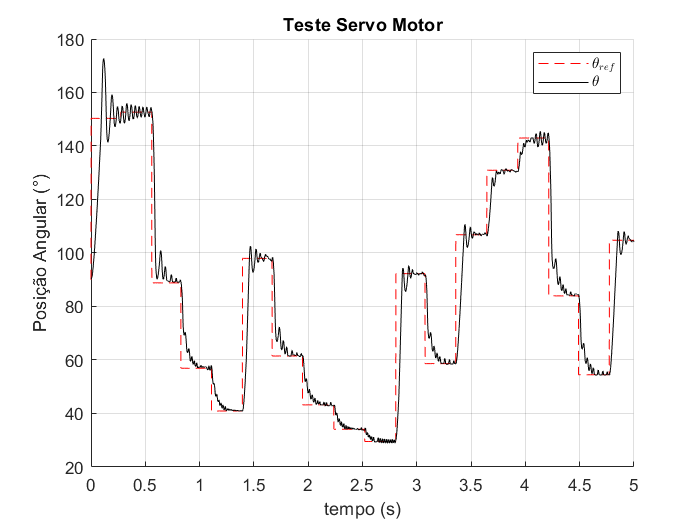

% plantaServo = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Motor Single link\PRBS-dinamica-servo-1ms-hold-50-19ms-susp-16-02-2024 10-14.csv");
plantaServo = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Motor Single link\PRBS-DINAMICA-SERVO-FINAL-susp-16-02-2024 12-37.csv");

refPosicao = plantaServo.U;
posicao = plantaServo.SL_position;

Ts = 1e-3;
[N, ~] = size(refPosicao);
tNoU = linspace(0, N, N)';

figure
hold on
grid
xlabel("tempo (s)")
ylabel("Posição Angular (°)");
plot(tNoU*Ts, refPosicao,'r--');
plot(tNoU*Ts, posicao,'k');
legend("$\theta_{ref}$", "$\theta$", 'interpreter', 'latex')
title("Teste Servo Motor");
xlim([0 5])
% axis([10 12 -15 15])
% legend("Disturbio senoidal 11.97V");

hold off